clc;
clear all; close all;
x1=zeros(1,5);
x2=ones (1,5);
xn=cat (2,x1,x2, x1,x2,x1,x2, x1, x2, x1, x2, x1, x2, x1,x2,x1,x2,x1,x2,x1,x2);
t=0:99;
% %generation of true channel response h(k.n)
hh11=unifrnd(0.4,1,1,100); 
hh22=unifrnd(0.75,0.98,1,100); 
hh1=fliplr(sort(hh11));
hh2=fliplr(sort (hh22));
h=[hh1;hh2]; 
sn=zeros(1,100);
xx=[0,xn];
for n=1:100 
    sn(n)=h(1,n)*xn(n)+h(2,n)*xx(n);
end
ww1=randn(1, 100); 
sigma2=0.1;   %varience of white noise R
w1=(ww1)*sqrt(0.1);
yn=sn+w1;     %Add noise to the system input
% initialization matrices
A=[0.99 0;0 0.999];
Q=[0.0001 0;0 0.0001]; 
hcap1=[0;0];     % Inital State of filter Coefficients
M1=100*eye(2,2); % Initial Varience
n=2;
for i=2:100
    hcap=A*hcap1;  %predicted state estimate (xcapk-)
    M=A*M1*A'+Q;   %varience of state estimate (Pk-)
    xtemp=[xn(n); xn(n-1)];  
    K=(M*xtemp)/(sigma2+(xtemp'*M*xtemp)); %Kalman Gain
    hcap1=hcap+K*(yn(n)-xtemp'*hcap);  % Updated state estimate xcapk
    M1=(eye(2,2)-K*xtemp')*M;   % varience of Updated state estimate Pk
    esthc(1,n)=hcap1(1);
    esthc(2,n)=hcap1(2);
    kalg(1,n)=K(1);
    kalg(2,n)=K(2);
    mse(1,n)=M1(1,1);
    mse(2,n)=M1(2,2); 
    n=n+1; 
end
fprintf('FINAL FILTER COEFFIECIENT ====>>')

FINAL FILTER COEFFIECIENT ====>>

esthc(:,100)

ans =     0.4673
    0.7618


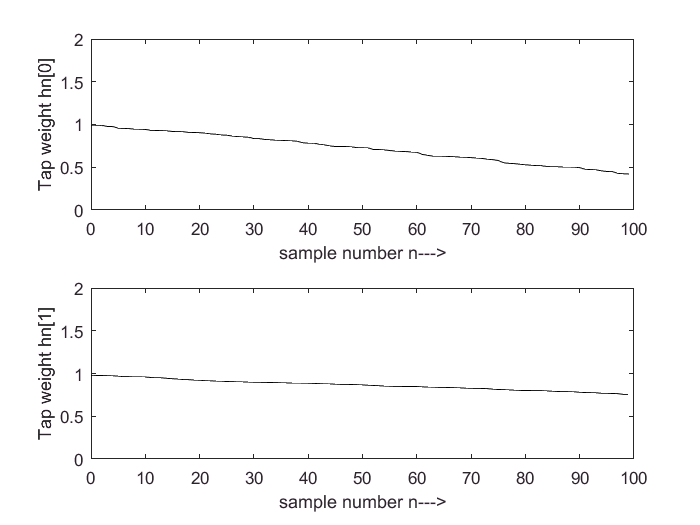

figure; 
subplot(2,1,1); 
plot(t,hh1,'k');
axis([0,100,0,2]);
xlabel('sample number n--->');ylabel('Tap weight hn[0]');

subplot (2,1,2); 
plot(t,hh2,'k');
axis([0,100,0,2]); 
xlabel('sample number n--->'); ylabel('Tap weight hn[1]'); 

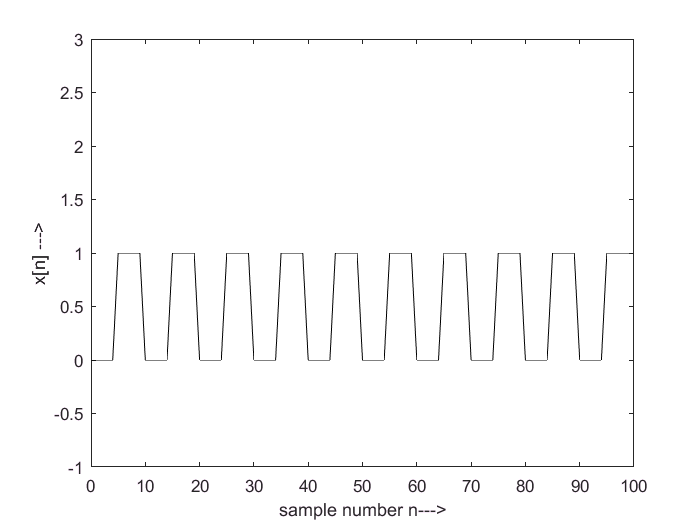


% title('True values of the weights')
figure;
plot(t,xn,'k'); 
axis([0,100,-1,3]);
xlabel ('sample number n--->');ylabel('x[n] --->');

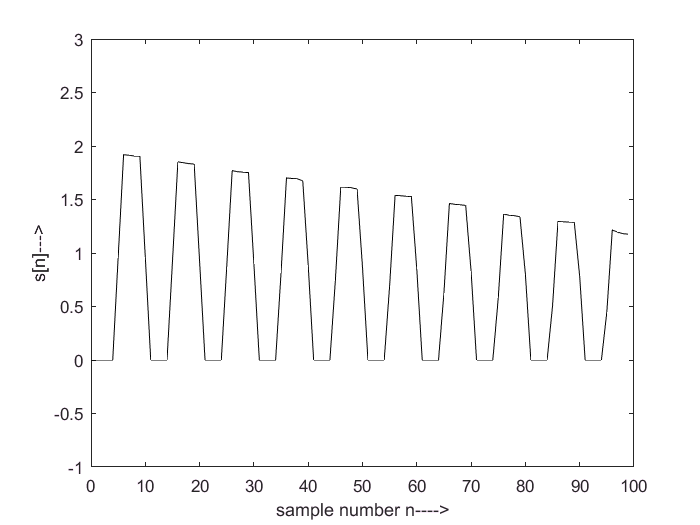


figure; 
plot(t,sn,'k');
axis([0,100,-1,3]);
xlabel ('sample number n---->');ylabel('s[n]--->');

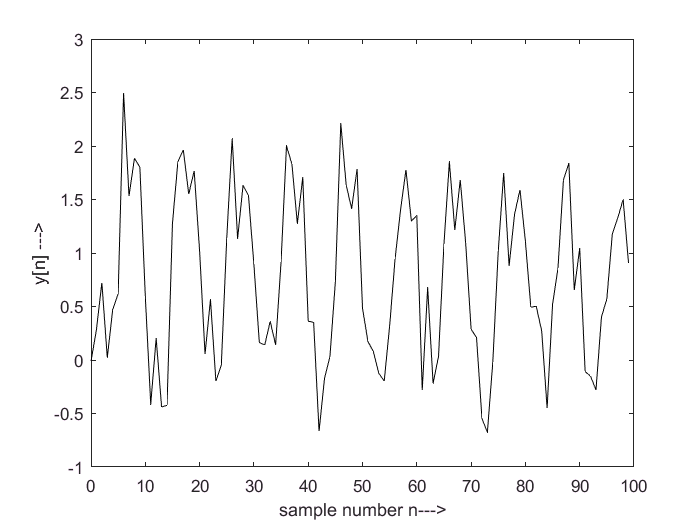


figure;
plot(t,yn,'k');
axis([0,100,-1,3]);
xlabel('sample number n--->');ylabel('y[n] --->');


figure; 
subplot(2,1,1),
plot (t,hh1,'-.');hold;plot(t,esthc(1,:), 'k'); 

Current plot held


axis([0,100,0,2]);
xlabel('sample number n--->');ylabel('Tap weight hn[0]');
subplot(2,1,2);
plot (t,hh2,'-.');hold;plot(t,esthc(2,:), 'k');

Current plot held


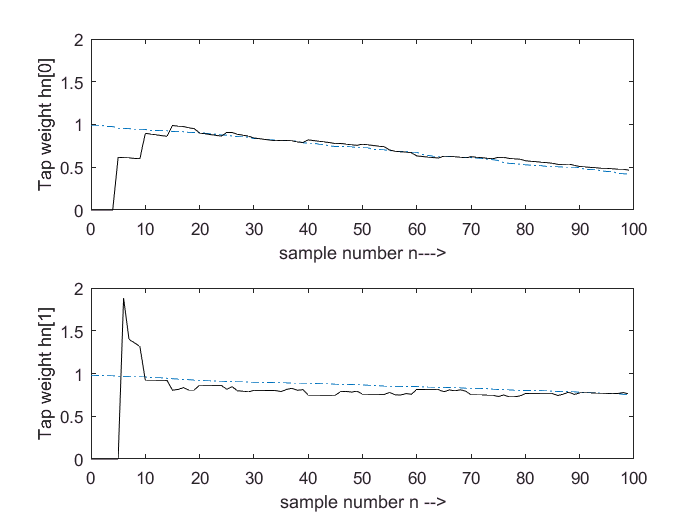

axis([0,100,0,2]);
xlabel('sample number n -->');ylabel('Tap weight hn[1]');

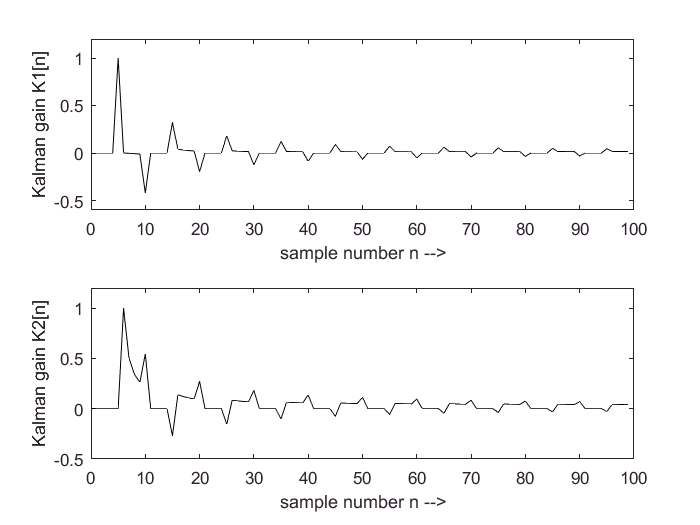


figure; 
subplot (2,1,1); 
plot(t,kalg(1,:),'k');
axis([0,100,-0.6,1.2]); 
xlabel('sample number n -->');ylabel('Kalman gain K1[n]');
subplot (2,1,2); 
plot(t,kalg(2,:),'k');
axis([0,100,-0.5,1.2]); 
xlabel('sample number n -->');ylabel('Kalman gain K2[n]');

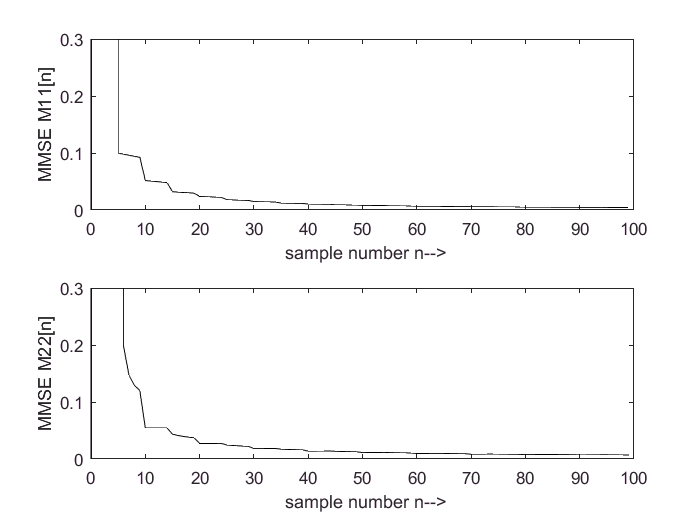



figure;
subplot(2,1,1);
plot(t,mse(1,:), 'k'); 
axis([0,100,0,0.3]);
xlabel(' sample number n-->'); ylabel("MMSE M11[n]");
subplot(2,1,2);
plot(t,mse(2,:), 'k'); 
axis([0,100,0,0.3]);
xlabel(' sample number n-->'); ylabel("MMSE M22[n]");